# Generate and Process Images

Gati Aher

SP2021: Quantitative Engineering Analysis Final Project

**Note:** this notebook requires MatLab Image Processing Toolbox

A notebook to generate simple geometric images.

% image size, all generated images will be N x N
N = 256;

## Generate Blank Image

img = zeros(N, N);
imwrite(img, "img/blank.png");

## Generate Simple Geometric Images

### Generate vertical, horizontal, and diagonal 2D sine plots

Play around with frequency! What do you observe if you change frequency to 5? 8? 10?

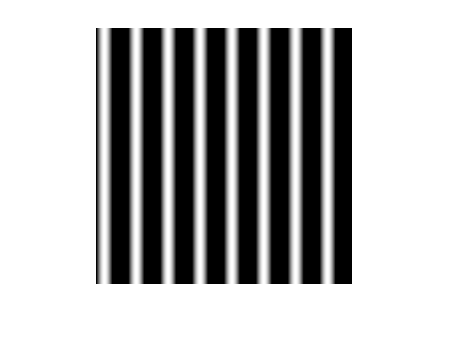

f = 8; % defines an angular frequency of 2pi*f

% vertical sine img
vertical_sine_img = repmat(sin(linspace(0,f*(2*pi),N)),[N 1]);
imshow(vertical_sine_img)

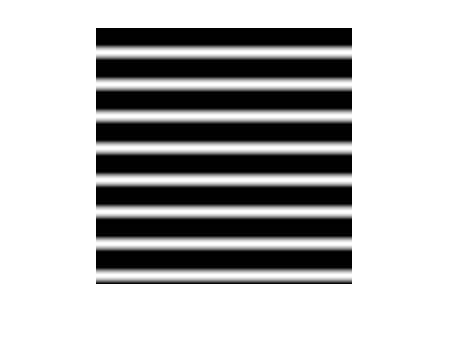

imwrite(vertical_sine_img, sprintf("img/vertical_sine_img_f%d.png", f))

% horizontal sine img
horizontal_sine_img = imrotate(vertical_sine_img, 90);
imshow(horizontal_sine_img)

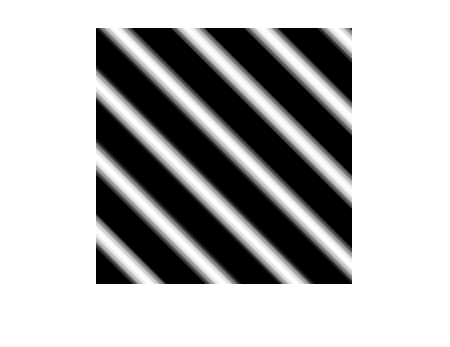

imwrite(horizontal_sine_img, sprintf("img/horizontal_sine_img_f%d.png", f))

% diagonal sine image, cropped and scaled to remove corners 
diagonal_sine_img = imcrop(imrotate(vertical_sine_img, 45), [100 100 N-100 N-100]);
diagonal_sine_img = imresize(diagonal_sine_img, N / size(diagonal_sine_img, 1));
imshow(diagonal_sine_img)

imwrite(diagonal_sine_img, sprintf("img/diagonal_sine_img_scaled_f%d.png", f));

### Generate Rectangles

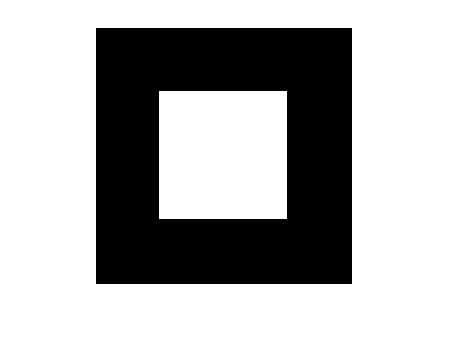

figure;
blank_img = zeros(N, N);
l = N/2;
s = (N - l) / 2;
img = insertShape(blank_img, 'FilledRectangle', [s s l l], "Color", "white", "Opacity", 1);
img = rgb2gray(img);
imshow(img);

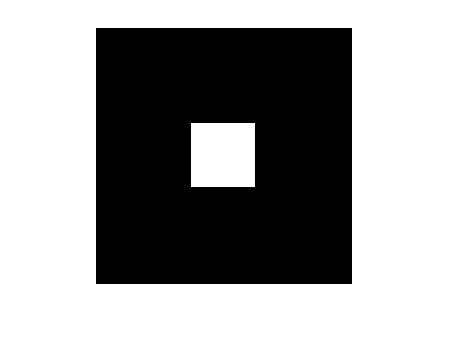

imwrite(img, sprintf("img/square_%dpx.png", l))

figure;
blank_img = zeros(N, N);
l = N/4;
s = (N - l) / 2;
img = insertShape(blank_img, 'FilledRectangle', [s s l l], "Color", "white", "Opacity", 1);
img = rgb2gray(img);
imshow(img);

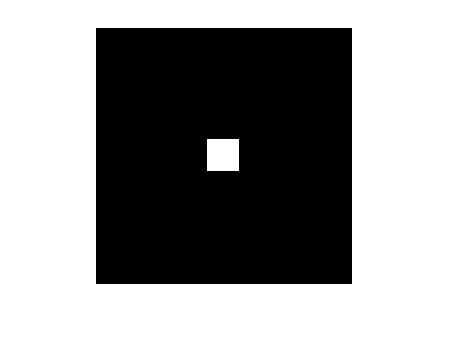

imwrite(img, sprintf("img/square_%dpx.png", l))

figure;
blank_img = zeros(N, N);
l = N/8;
s = (N - l) / 2;
img = insertShape(blank_img, 'FilledRectangle', [s s l l], "Color", "white", "Opacity", 1);
img = rgb2gray(img);
imshow(img);

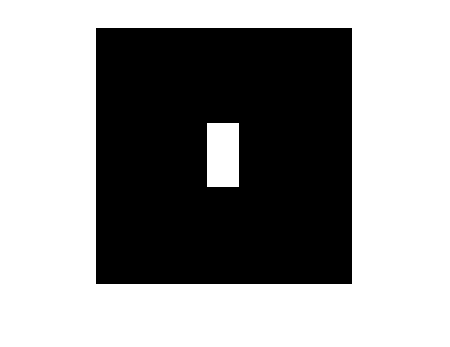

imwrite(img, sprintf("img/square_%dpx.png", l))

figure;
blank_img = zeros(N, N);
l = N/8;
s = (N - l) / 2;
l2 = N/4;
s2 = (N - l2) / 2;
img = insertShape(blank_img, 'FilledRectangle', [s s2 l l2], "Color", "white", "Opacity", 1);
img = rgb2gray(img);
imshow(img);

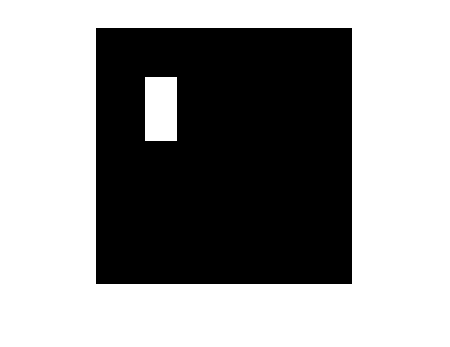

imwrite(img, sprintf("img/rect_%dx%dpx.png", l, l2))


figure;
blank_img = zeros(N, N);
l = N/8;
s = 50;
l2 = N/4;
s2 = s;
img = insertShape(blank_img, 'FilledRectangle', [s s2 l l2], "Color", "white", "Opacity", 1);
img = rgb2gray(img);
imshow(img);

imwrite(img, sprintf("img/rect_%dx%dpx_offset_by_%d.png", l, l2, s))

### Generate Circles

Make a solid circle

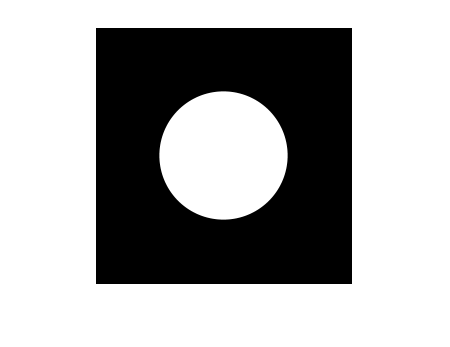

figure;
blank_img = zeros(N, N);
l = N/4;
s = N / 2;
img = insertShape(blank_img, 'FilledCircle', [s, s, l], "Color", "white", "Opacity", 1);
img = rgb2gray(img);
imshow(img);

imwrite(img, sprintf("img/circle_r%dpx.png", l))

Make a Gaussian Circle

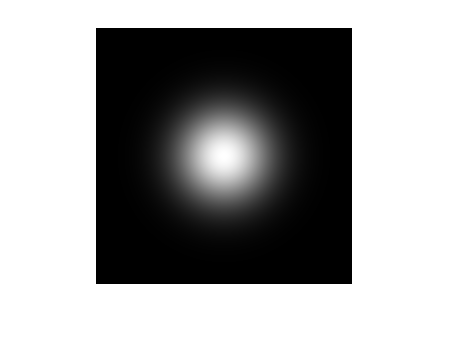

% centered
sigma = 100; % standard deviation
filt_size = 2; % size of filter
x = linspace(-filt_size*sigma,filt_size*sigma, N);
y = x;
[X,Y] = meshgrid(x,y);
intensity = exp(-filt_size * (X.^2 + Y.^2) / sigma^2);
figure
imshow(intensity)

imwrite(intensity, sprintf("img/circle_sigma%d_size%d.png", sigma, filt_size))

### Generate Diagonal Line

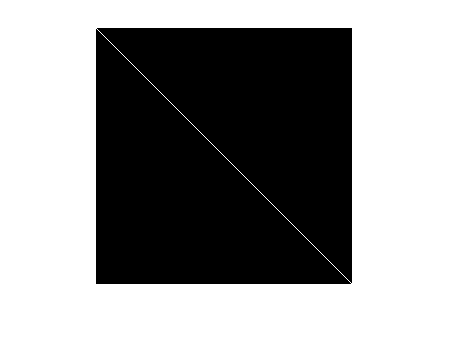

D = diag(ones(N, 1));
imshow(D)

imwrite(D, "img/diagonal_lines.png")

## Generate Random Noise

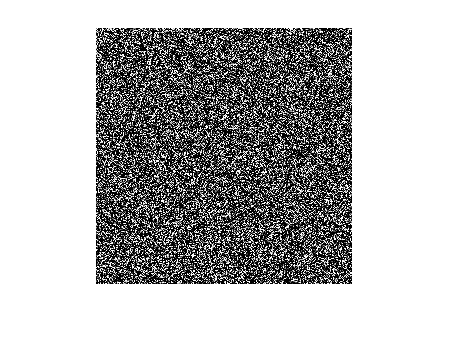

noise = randn(N, N);
imshow(noise)

imwrite(noise, "img/noise.png");

### Process Natural Pattern Images

Turn images to greyscale and resample so they are NxN pixels

Brick

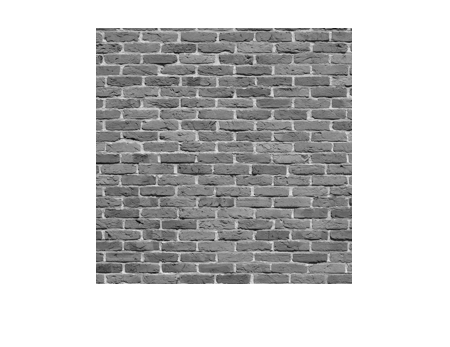

img = imread("natural_pattern_img/brick.jpg");
img = rgb2gray(img);
img = imresize(img, N/size(img, 1));
img = imcrop(img, [0 0 N N]);
imshow(img)

imwrite(img, "img/brick.png")

Mustard Seed

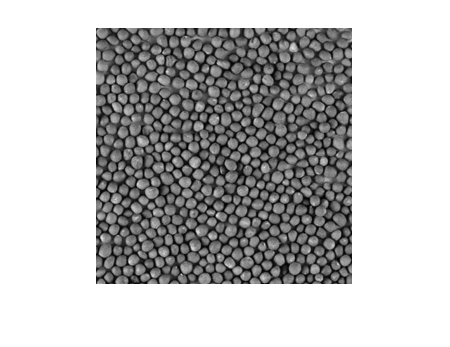

img = imread("natural_pattern_img/mustard_seeds.jpg");
img = rgb2gray(img);
img = imresize(img, N/size(img, 1));
img = imcrop(img, [0 0 N N]);
imshow(img)

imwrite(img, "img/mustard_seeds.png")

Sugar Cube

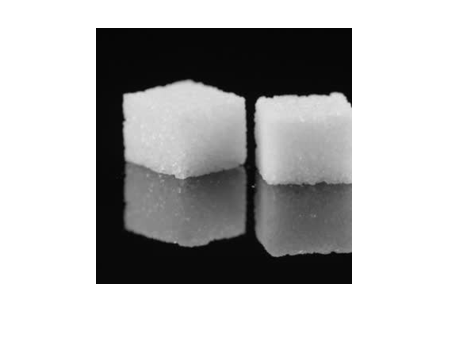

img = imread("natural_pattern_img/sugar_cube.jpg");
img = rgb2gray(img);
img = imresize(img, N/size(img, 1));
img = imcrop(img, [0 0 N N]);
imshow(img)

imwrite(img, "img/sugar_cube.png")

Honeycomb

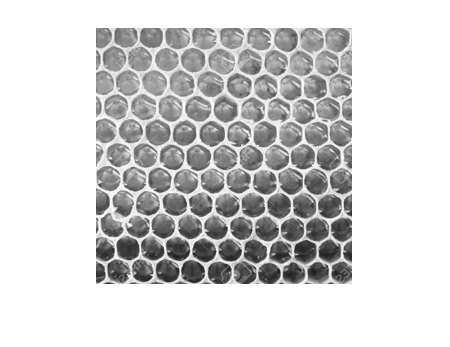

img = imread("natural_pattern_img/honeycomb.jpg");
img = rgb2gray(img);
img = imresize(img, N/size(img, 1));
img = imcrop(img, [0 0 N N]);
imshow(img)

imwrite(img, "img/honeycomb.png")

## Process Complex Images

Turn images to greyscale and resample so they are NxN pixels

The camera-man (famous in image processing)

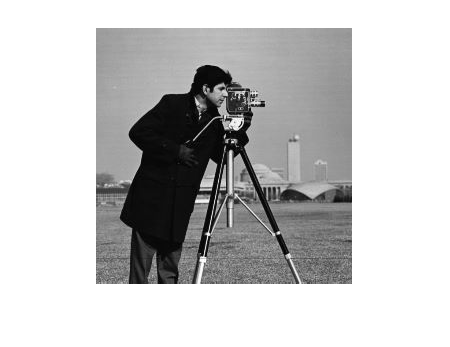

img = imread("complex_img/cameraman.jpg");
img = rgb2gray(img);
img = imresize(img, N/size(img, 1));
img = imcrop(img, [0 0 N N]);
imshow(img)

imwrite(img, "img/cameraman.png")

Flower (from Gati's Garden)

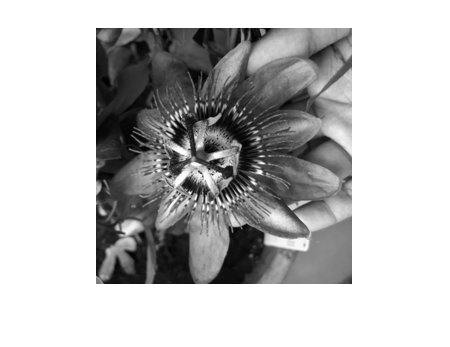

img = imread("complex_img/flower.jpg");
img = rgb2gray(img);
img = imresize(img, N/size(img, 2));
img = imcrop(img, [0 0 N N]);
imshow(img)

imwrite(img, "img/flower.png")

Bacteria S-Layer (from Gati's Research)

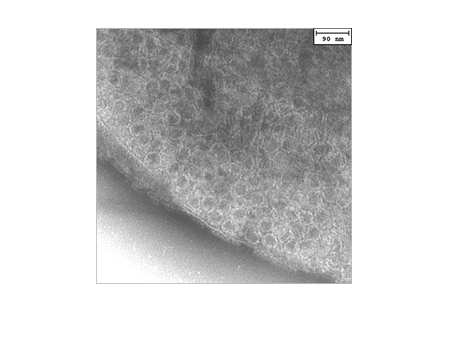

img = imread("complex_img/bacteria_slayer.tif");
img = imresize(img, N/size(img, 1));
img = imcrop(img, [0 0 N N]);
imshow(img)

imwrite(img, "img/bacteria_slayer.png")